% This function gets the input resistances of cells from cellList using the
% ramp stimulus.
% Rinput = %(V2-V1)/(I2-I1)... in other words, the slope of the ramp when
% plotted in the I-V plane

ups = grabFromFilter('UP Cells');
downs = grabFromFilter('DOWN Cells');

%choose which protocols to look at
priorityOrder_1 = {'Ramp'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_ff'; 'CurrentClamp'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {''};
cantHave_1 = [];
cantHave_2 = {'Cesium', 'Extracellular'}; %avoid anything with these tags
rigMandates = [];

upInputResistances = [];
upCVCorrCoefs = [];
upSlopeRatios = [];
unames = {};
peakSpikeHeightUp = [];
%loop through cell list
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    %ask whether the current cell has the requested analysis
    [rampLoc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    if pass
        continue
    end
    
    clarinetExport = getClarinetExport(struct_i);
    exampleEpoch = clarinetExport(rampLoc.Analysis_Results.EpochNumbers(1)).epoch;
    peakSpikeHeight = max(exampleEpoch);
    maxPeak = rampLoc.Analysis_Results.rampAmplitude;
    peakSpikeHeightUp(end + 1) = peakSpikeHeight;
    if peakSpikeHeight < 10
        continue
    end
    
    unames(end+1) = {struct_i.cellID};
    
    %     figure
    %     title(struct_i.cellID)
    %     hold on
    %     plot(exampleEpoch)
    %     hold off
    
    inputRs = zeros(1, numel(rampLoc.Analysis_Results.EpochNumbers));
    r_squared = zeros(1, numel(rampLoc.Analysis_Results.EpochNumbers));
    firstHalfSlopes = zeros(1, numel(rampLoc.Analysis_Results.EpochNumbers));
    secondHalfSlopes = zeros(1, numel(rampLoc.Analysis_Results.EpochNumbers));
    for j = 1:numel(inputRs)
        restingPotential = rampLoc.Analysis_Results.restingMembranePotentialByEpoch(j); %mV
        thresholdPotential = rampLoc.Analysis_Results.thresholdByEpoch(j); %mV
        
        spikeTimes_j = rampLoc.Analysis_Results.allSpikeTimes{j};
        firstSpikeTime = spikeTimes_j(1) - 2; %ms... subtracting 2ms because spiketime indicates the peak of the spike
        preTime = rampLoc.meta.preTime; %ms
        
        timeToThreshold = firstSpikeTime - preTime; %ms - amount of time after stimulus onset that it took to reach threshold potential
        
        rampAmplitude = rampLoc.meta.rampAmplitude; %pA
        rampDuration = rampLoc.meta.stimTime; %ms
        
        currentSlope = rampAmplitude/rampDuration; %pA/ms
        
        currentAtThreshold = currentSlope * timeToThreshold; %pA - the amount of current that was being injected at threshold
        
        inputRs(j) = 1e9*(thresholdPotential-restingPotential)/currentAtThreshold; %Ohms
        
        fullTrace = clarinetExport(rampLoc.Analysis_Results.EpochNumbers(j)).epoch;
        rampPoints = fullTrace(preTime*10:round((firstSpikeTime-2)*10));
        r_squared(j) = corr(rampPoints');
        
        halfway_time = timeToThreshold/2;
        halfway_current = currentSlope * halfway_time;
        halfway_voltage = fullTrace(round(preTime+halfway_time)*10);
        firstHalfSlopes(j) = (halfway_voltage-restingPotential)/(halfway_current);
        secondHalfSlopes(j) = (thresholdPotential-halfway_voltage)/(currentAtThreshold-halfway_current);
    end
    
    upInputResistances(end+1) = mean(inputRs);
    upCVCorrCoefs(end + 1) = mean(r_squared);
    upSlopeRatios(end + 1) = mean(firstHalfSlopes./secondHalfSlopes);
end

downInputResistances = [];
downCVCorrCoefs = [];
downSlopeRatios = [];
dnames = {};
peakSpikeHeightDown = [];
%loop through cell list
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    %ask whether the current cell has the requested analysis
    [rampLoc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    if pass
        continue
    end
    clarinetExport = getClarinetExport(struct_i);
    exampleEpoch = clarinetExport(rampLoc.Analysis_Results.EpochNumbers(1)).epoch;
    peakSpikeHeight = max(exampleEpoch);
    maxPeak = rampLoc.Analysis_Results.rampAmplitude;
    peakSpikeHeightDown(end + 1) = peakSpikeHeight;
    if peakSpikeHeight < 10
        continue
    end
    
%     figure
%     title(struct_i.cellID)
%     hold on
%     plot(exampleEpoch)
%     hold off
%     
    dnames(end+1) = {struct_i.cellID};
    inputRs = zeros(1, numel(rampLoc.Analysis_Results.EpochNumbers));
    r_squared = zeros(1, numel(rampLoc.Analysis_Results.EpochNumbers));
    firstHalfSlopes = zeros(1, numel(rampLoc.Analysis_Results.EpochNumbers));
    secondHalfSlopes = zeros(1, numel(rampLoc.Analysis_Results.EpochNumbers));
    for j = 1:numel(inputRs)
        restingPotential = rampLoc.Analysis_Results.restingMembranePotentialByEpoch(j); %mV
        thresholdPotential = rampLoc.Analysis_Results.thresholdByEpoch(j); %mV
        
        spikeTimes_j = rampLoc.Analysis_Results.allSpikeTimes{j};
        firstSpikeTime = spikeTimes_j(1) - 2; %ms... subtracting 2ms because spiketime indicates the peak of the spike
        preTime = rampLoc.meta.preTime; %ms
        
        timeToThreshold = firstSpikeTime - preTime; %ms - amount of time after stimulus onset that it took to reach threshold potential
        
        rampAmplitude = rampLoc.meta.rampAmplitude; %pA
        rampDuration = rampLoc.meta.stimTime; %ms
        
        currentSlope = rampAmplitude/rampDuration; %pA/ms
        
        currentAtThreshold = currentSlope * timeToThreshold; %pA - the amount of current that was being injected at threshold
        
        inputRs(j) = 1e-3*(thresholdPotential-restingPotential)/(currentAtThreshold*1e-12); %Ohms
        
        fullTrace = clarinetExport(rampLoc.Analysis_Results.EpochNumbers(j)).epoch;
        rampPoints = fullTrace(preTime*10:round((firstSpikeTime-2)*10));
        r_squared(j) = corr(rampPoints');
        
        halfway_time = timeToThreshold/2;
        halfway_current = currentSlope * halfway_time;
        halfway_voltage = fullTrace(round(preTime+halfway_time)*10);
        firstHalfSlopes(j) = (halfway_voltage-restingPotential)/(halfway_current);
        secondHalfSlopes(j) = (thresholdPotential-halfway_voltage)/(currentAtThreshold-halfway_current);
    end
    
    downInputResistances(end+1) = mean(inputRs);
    downCVCorrCoefs(end + 1) = mean(r_squared);
    downSlopeRatios(end + 1) = mean(firstHalfSlopes./secondHalfSlopes);
end

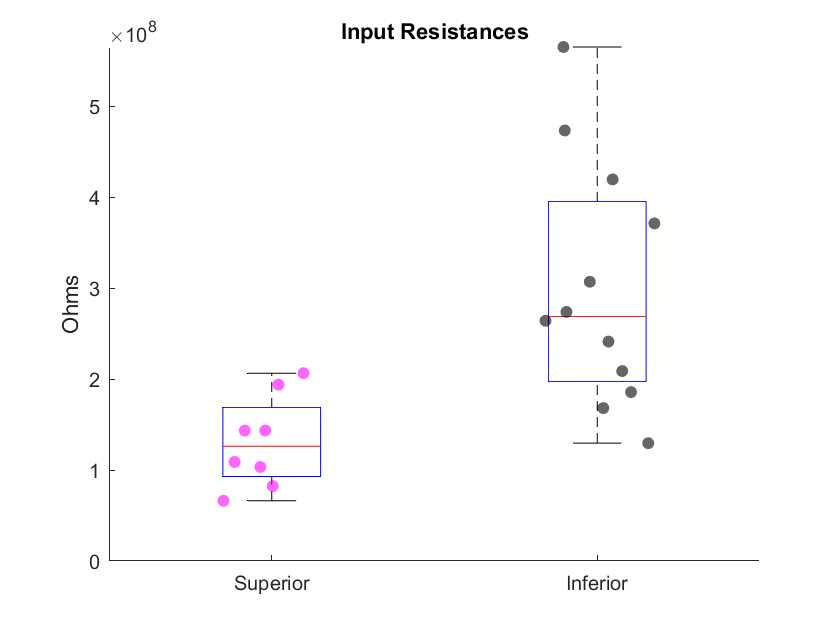

allIRs = [downInputResistances, upInputResistances];
boxPlotGroups = zeros(1, numel(allIRs));
boxPlotGroups(numel(downInputResistances)+1:end) = 1;

figure
title('Input Resistances')
hold on
boxplot(allIRs, boxPlotGroups)
scatter(zeros(1, numel(downInputResistances))+1, downInputResistances, 'm', 'filled', 'MarkerFaceAlpha', 0.6, 'jitter', 'on')
scatter(zeros(1, numel(upInputResistances))+2, upInputResistances, 'k', 'filled', 'MarkerFaceAlpha', 0.6, 'jitter', 'on')
ylabel('Ohms')
box off
xticklabels({'Superior', 'Inferior'})
ylim([0 inf])

p = ranksum(downInputResistances, upInputResistances)

p = 0.0023

## Linearity of Current-Voltage Relationship

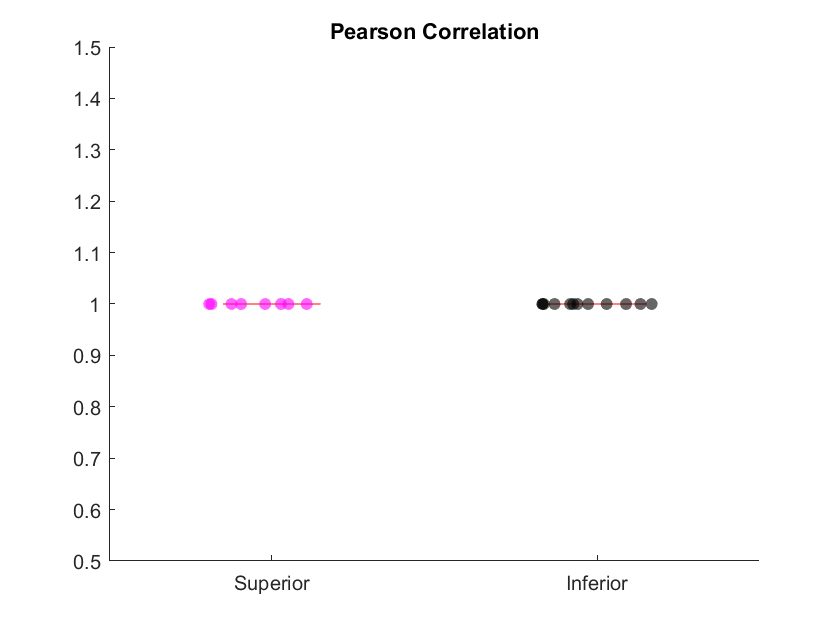

allCVs = [downCVCorrCoefs, upCVCorrCoefs];
boxPlotGroups = zeros(1, numel(allCVs));
boxPlotGroups(numel(downCVCorrCoefs)+1:end) = 1;

figure
title('Pearson Correlation')
hold on
boxplot(allCVs, boxPlotGroups)
scatter(zeros(1, numel(downCVCorrCoefs))+1, downCVCorrCoefs, 'm', 'filled', 'MarkerFaceAlpha', 0.6, 'jitter', 'on')
scatter(zeros(1, numel(upCVCorrCoefs))+2, upCVCorrCoefs, 'k', 'filled', 'MarkerFaceAlpha', 0.6, 'jitter', 'on')
box off
xticklabels({'Superior', 'Inferior'})

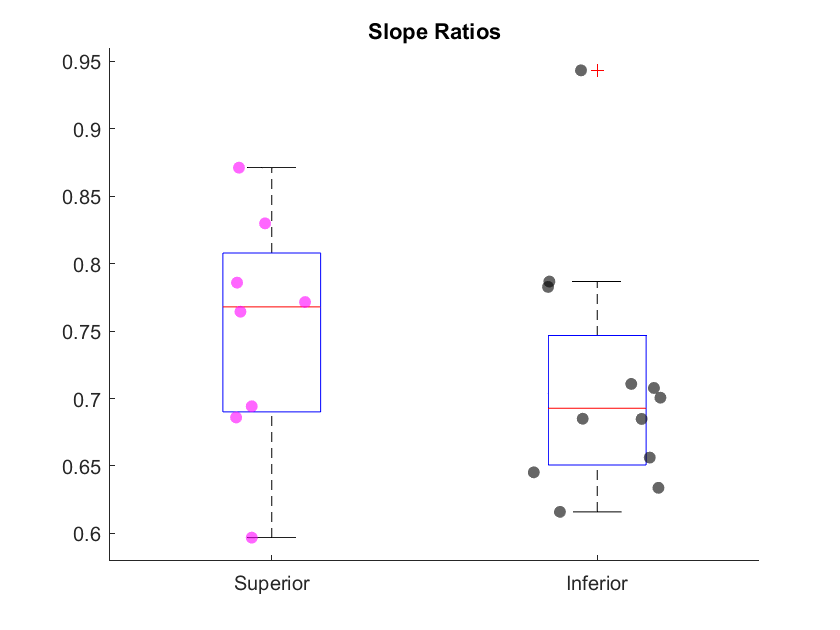

allRatios = [downSlopeRatios, upSlopeRatios];
boxPlotGroups = zeros(1, numel(allRatios));
boxPlotGroups(numel(downSlopeRatios)+1:end) = 1;

figure
title('Slope Ratios')
hold on
boxplot(allRatios, boxPlotGroups)
scatter(zeros(1, numel(downSlopeRatios))+1, downSlopeRatios, 'm', 'filled', 'MarkerFaceAlpha', 0.6, 'jitter', 'on')
scatter(zeros(1, numel(upSlopeRatios))+2, upSlopeRatios, 'k', 'filled', 'MarkerFaceAlpha', 0.6, 'jitter', 'on')
box off
xticklabels({'Superior', 'Inferior'})